# Mess- und Regelungstechnik - Praktikum 3

Prof. Dr.-Ing. Anselm Haselhoff - Hochschule Ruhr West

## Aufgabe 1:

Mit der beigefügten Funktion `measure` wird ein Fahrtverlauf zweier Autos simuliert, die mit einem angegebenen Abstand zueinander fahren. Die Funktion gibt die Messwerte eines Abstandssensors zurück, der am hinteren Auto angebracht ist und den Abstand 50 Mal pro Sekunde in Metern misst. Sie werden feststellen, dass die Messwerte des Sensor nicht unerheblich von dem wahren Wert abweichen.

### 1)

Nehmen Sie eine Messung für n=250 Messwerte, also 5 Sekunden, bei einem Abstand von 15 Metern auf.

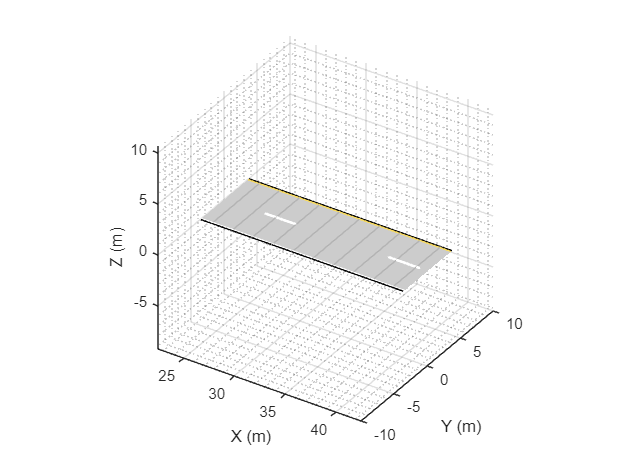

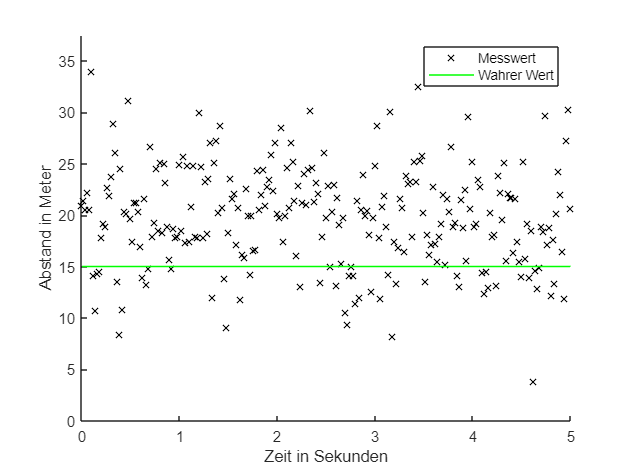

n = 250;
dist = 15;
Z = measure(250,15);

### 2)

Berechnen Sie nun mit den Formeln aus der Vorlesung den Mittelwert und die Standardabweichung der Messreihe. Sie können auch die Matlab internen Funktionen verwenden (`mean`, `std`).

meanZ = mean(Z);
stdZ = std(Z);

disp("Der Mittelwert der Messreihe beträgt: " + meanZ);

Der Mittelwert der Messreihe beträgt: 19.7452


disp("Die Standardabweichung der Messreihe beträgt: " + stdZ);

Die Standardabweichung der Messreihe beträgt: 4.9153


### 3)

Bestimmen Sie die Standardabweichung des Mittelwertes. Wie lautet das Vertrauensintervall $x=\bar{x}\pm t \frac{s}{\sqrt{n}}$ für den Mittelwert bei einem Vertrauensniveau von $\gamma = \{ 90\%, 95\%, 99 \% \}$? Erstellen Sie zur Berechnung des Faktors $t$ eine Funktion und nutzen Sie `tinv(p,n-1)`. Kontrollieren Sie ihre Funktion mit den Werten $\gamma = \{ 90\%, 95\%, 99 \% \}$, $n= 3\Rightarrow t=\{2.92,4.3,9.93\}$. Hinweis zur Berechnung der Vertrauensgrenze: Gesucht ist $t$ für das zweiseitige Vertrauensniveau, d.h. $Pr\left(-t<T<t\right)=\int_{-t}^tf(t)dt$ (Fläche unter f(t) zwischen -t und t, vgl. Abbildung). Mit der Matlab-Funktion kann nur das einseitige Vertrauensniveau $p=Pr\left(T<a\right)=\int_{-\infty}^af(t)dt$ berechnet werden (`a=tinv(p,n-1)`). Tipp: Für das Integral gilt $\int_{-\infty}^\infty f(t)dt=1$.  

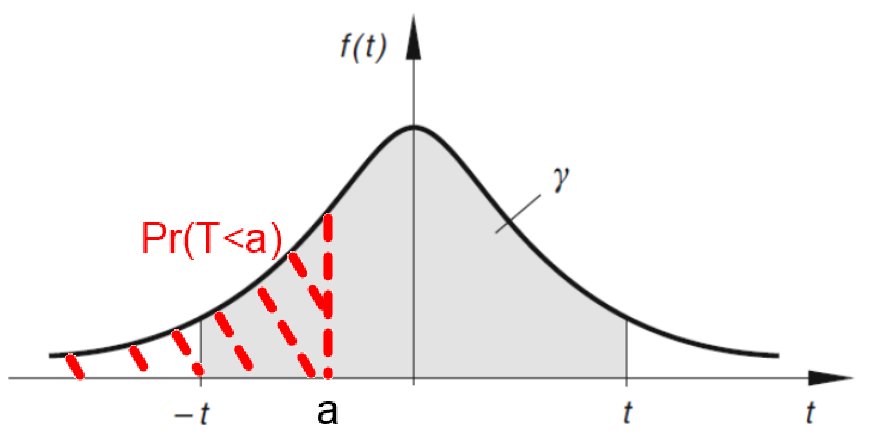

stdOfMeanZ = stdZ ./ sqrt(n);
disp("Die Standardabweichung des Mittelwerts beträgt: " + stdOfMeanZ);

Die Standardabweichung des Mittelwerts beträgt: 0.31087



t1 = calculateT(90, 3);
disp("Parameter t für 90%: " + t1);

Parameter t für 90%: 2.92


upperForT1 = meanZ + t1 * stdOfMeanZ;
lowerForT1 = meanZ - t1 * stdOfMeanZ;
disp("Obere Vertrauensgrenze: " + upperForT1);

Obere Vertrauensgrenze: 20.653


disp("Untere Vertrauensgrenze: " + lowerForT1);

Untere Vertrauensgrenze: 18.8375



t2 = calculateT(95, 3);
disp("Parameter t für 95%: " + t2);

Parameter t für 95%: 4.3027


upperForT2 = meanZ + t2 * stdOfMeanZ;
lowerForT2 = meanZ - t2 * stdOfMeanZ;
disp("Obere Vertrauensgrenze: " + upperForT2);

Obere Vertrauensgrenze: 21.0828


disp("Untere Vertrauensgrenze: " + lowerForT2);

Untere Vertrauensgrenze: 18.4077



t3 = calculateT(99, 3);
disp("Parameter t für 99%: " + t3);

Parameter t für 99%: 9.9248


upperForT3 = meanZ + t3 * stdOfMeanZ;
lowerForT3 = meanZ - t3 * stdOfMeanZ;
disp("Obere Vertrauensgrenze: " + upperForT3);

Obere Vertrauensgrenze: 22.8306


disp("Untere Vertrauensgrenze: " + lowerForT3);

Untere Vertrauensgrenze: 16.6599


### 4)

Geben Sie das Messergebnis aus (obere und untere Vertrauensgrenze). Passt der ermittelte Messwert mit dem wahren Wert zusammen und liegt er in den Vertrauensgrenzen? Wie erklären Sie sich das Ergebnis?

% Der reale Wert liegt nicht in den Vertrauensgrenzen, das liegt zu
% einen an dem weit vom realen Wert entfernten Mittelwert selbst und zu
% anderen an der sehr geringen Standardabweichung um den Mittelwert. Beide Werte werden
% zur Berechung der Vertrauensgrenzen benötigt und beeinflussen damit maßgeblich den Vertrauensbereich.
% Denmach kann man schlussfolgern, dass der Sensor noch
% nicht optimal funktioniert.
% systematische Abweichung von etwa 5m eigentlich sollt man nicht so weit
% auswerten, da die systematische Abweichung schon so hoch ist

### 5)

Erstellen Sie ein Histogramm der Messwerte mit 25 Intervallen. Nutzen Sie die Funktion `histogram`. Was können Sie hier erkennen?

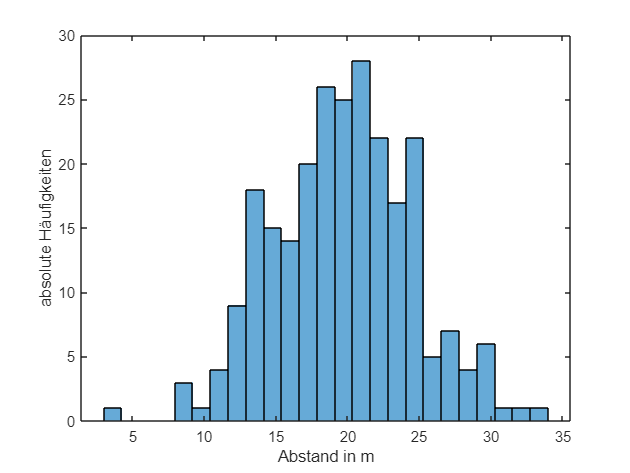

histogram(Z,25);
ylabel("absolute Häufigkeiten");
xlabel("Abstand in m");

% Ähnelt stark einer Normalverteilung. Der berechnete Mittelwert von rund
% 20 stimmt einigermaßen überein.
% Unser realer Wert liegt nur knapp im ein Sigamaintervall.